clear;
load('config.mat', "dirname", "block_Nx", "block_Ny");
dirname = '.\20200420T233522\';
block_Nx = 2;
block_Ny = 2;
tagPath = dirname;


## 循环读取 12 个 beacon 的数据

N_beacon = 12;
beacon = 0;

for i=1:N_beacon
    filename = sprintf('%s%s%d.mat', tagPath, 'Beacon_sig_proc_', i);
    load(filename, 'y_smooth');
    if i == 1
        beacon = y_smooth';
    else
        beacon = [beacon; y_smooth'];
    end
end


## 循环读取 tag 的数据

N_tag = block_Nx * block_Ny;
tag = 0;

for i=1:N_tag
    filename = sprintf('%s%s%d.mat', tagPath, 'sig_proc_', i);
    load(filename, 'y_smooth');
    if i == 1
        tag = y_smooth';
    else
        tag = [tag; y_smooth'];
    end
end


## 计算 tag 和 beacon 的距离

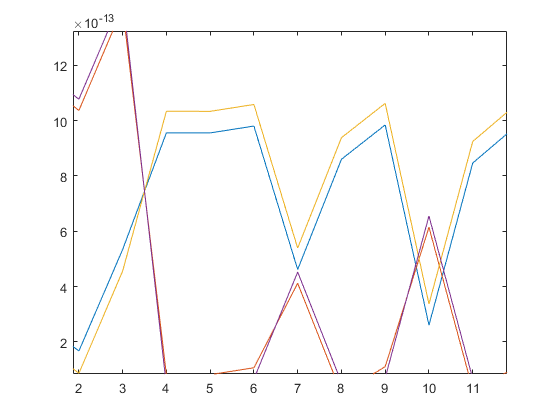

y_sig =  [beacon;tag];
D = pdist(y_sig);
D = squareform(D);
distance = D(N_beacon + 1:end, 1:N_beacon)';
figure;plot(distance);

%% 保存
filename = sprintf('%s%s.mat', tagPath, 'distance');
save(filename, 'distance');

## 读取房内和房外的数据

load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

% inside
y_in = 0;
for i=1:N_inside
    filename = sprintf('%s%s%d.mat', ioPath, 'i_sig_proc_', i);
    load(filename, 'y_smooth');
    if i == 1
        y_in = y_smooth';
    else
        y_in = [y_in; y_smooth'];
    end
end

% outside
y_out = 0;
for i=1:N_outside
    filename = sprintf('%s%s%d.mat', ioPath, 'o_sig_proc_', i);
    load(filename, 'y_smooth');
    if i == 1
        y_out = y_smooth';
    else
        y_out = [y_out; y_smooth'];
    end
end

## 计算内外样本点和 beacon 的距离

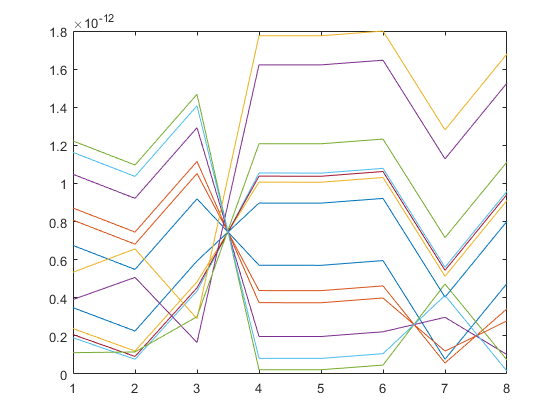

y_io = [beacon ; y_in ; y_out];
D_io = pdist(y_io);
D_io = squareform(D_io);
distance_io = D_io(N_beacon + 1:end, 1:N_beacon)';
figure;plot(distance_io(1:N_inside,:));

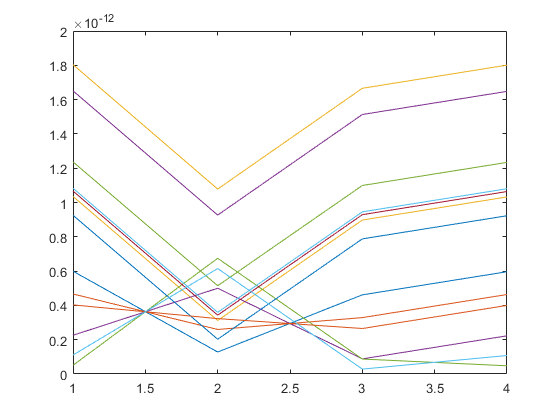

figure;plot(distance_io(N_inside+1:end,:));

%% 保存
filename = sprintf('%s%s.mat', tagPath, 'distance_io');
save(filename, 'distance_io');
